## Test Network

addpath('C:\Users\feder\Dropbox\Tesi Finotto\matlab\code');
addpath('C:\Users\feder\Dropbox\Tesi Finotto\matlab\code\Datasets\');
addpath('C:\Users\feder\Dropbox\Tesi Finotto\matlab\code\functions\');

This code block sets up the test set for evaluation. The variable `TrainSetting.nTestPattern` is initially set to 0, which means that the test set will not be cut. If `TrainSetting.nTrainPattern` is not 0, it indicates that the training set is cut, so the code finds the maximum length pattern of the training set.

The for loop goes through the test set, and if the size of the test pattern is less than the maximum length of the training set, it updates the `TrainSetting.nTestPattern` variable to the current position. When the size of the test pattern is greater than or equal to the maximum length of the training set, the loop is stopped.

The input and output data are then extracted from the test set and assigned to `XTest` and `TTest` respectively.

If `TrainSetting.nTestPattern` is not 0, it means that the number of test patterns to be used is specified, so the number of patterns in `XTest` and `TTest` is reduced to `TrainSetting.nTestPattern` to keep the statistics coherent with the used train set.

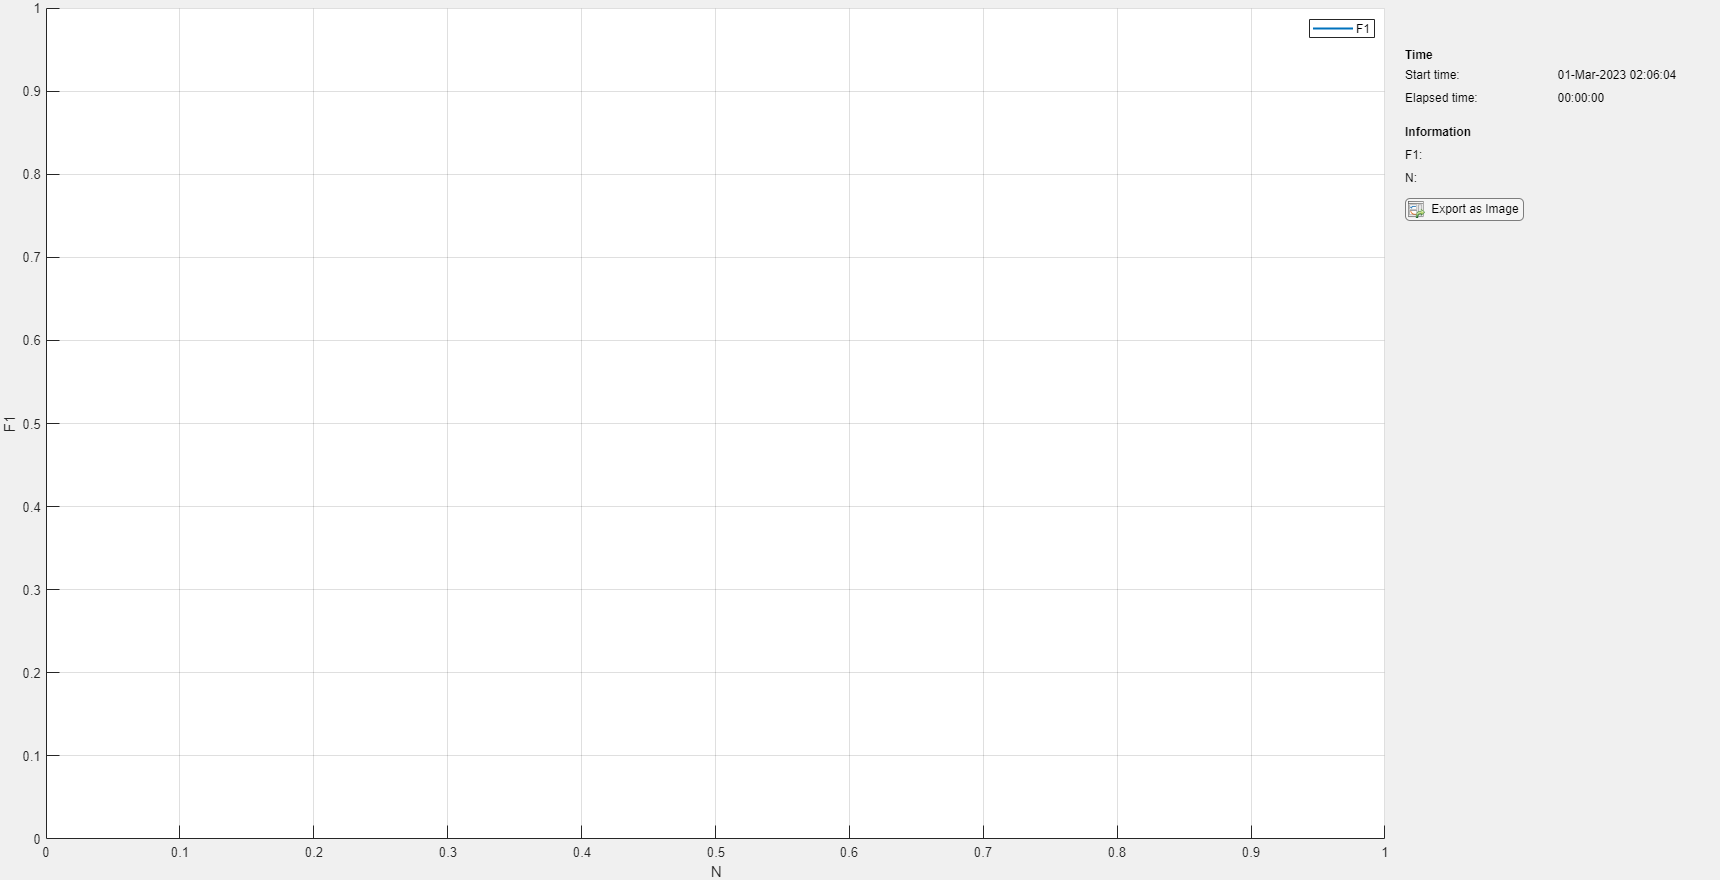

TestMonitor = trainingProgressMonitor(Metrics="F1",Info=["N","F1"],XLabel="N");


TrainSetting.nTestPattern = 0;      % If remain 0 the TestSet will not be cutted
if(TrainSetting.nTrainPattern~=0)   % If training set is cutted
    %find the max length pattern of training set
    maxNetTrainSize = dataset.train(TrainSetting.nTrainPattern).size; 
    for i = 1:length(dataset.test)
        % find the position of the last pattern under that dimension
        if (dataset.test(i).size < maxNetTrainSize)
            TrainSetting.nTestPattern = i;
        else
            break;
        end
    end
end
% Extract the input and output data from the test dataset
XTest = {dataset.test.input};
TTest = {dataset.test.output};

% If the number of test patterns to be used is specified
% then the number of patterns in XTest and TTest is reduced to TrainSetting.nTestPattern.
% This is done to keep statistic coherent with the train set Used
if(TrainSetting.nTestPattern~=0)
    XTest = XTest(1:TrainSetting.nTestPattern);
    TTest = TTest(1:TrainSetting.nTestPattern);
end

Defines four variables, FP, FN, TP, and DIM, which are all initialized to 0. Then it loops through each element in XTest, a cell array of RNA sequences, and applies a neural network, net, to the sequence using the RNA2Net function. The resulting matrix is compared to the expected output, TTest, by using the MatriceT function to convert the expected output to a binary matrix. The number of true positives, false positives, and false negatives are calculated using the sum function and saved in the respective variables, TP, FP, and FN. The length of the expected output is also saved in the DIM variable. The loop iterates through all the sequences in XTest and calculates these values for each.

N = size(XTest,2);
FP = zeros(N,1,"double");
FN = zeros(N,1,"double");
TP = zeros(N,1,"double");
DIM = zeros(N,1,"double");
dati = struct("StringInput","","TensorInput",[],"TMatrix",[],"ProbOutput",[],"BinaryOutput",[],"Dimension",0,"TP",0,"FP",0,"FN",0,"F1",0,"Precision",0,"Recall",0);

for i=1:N
    dati(i).StringInput = XTest{i};
    dati(i).TensorInput = Tensor8(dati(i).StringInput);
    dati(i).ProbOutput = dlarray(forward(net,dlarray(single(dati(i).TensorInput),"SSCB")),"SSCB");
    dati(i).BinaryOutput = outputMatrix(dati(i).ProbOutput);
    dati(i).TMatrix = MatriceT(TTest{i});
    
    %fprintf("Elaborate: %d/%d\n",i,N);
    Y = dati(i).BinaryOutput;
    T = dati(i).TMatrix;

    TP(i) = sum(Y==1 & T==1,"all");
    FP(i) = sum(Y==1 & T==0,"all");
    FN(i) = sum(Y==0 & T==1,"all");
    DIM(i) = length(T);

    Prec = TP(i)/TP(i)+FP(i);
    Rec = TP(i)/TP(i)+FN(i);
    F1_temp = 2*(Prec*Rec)/(Prec+Rec);
    
    dati(i).Dimension = length(T);
    dati(i).TP = TP(i);
    dati(i).FP = FP(i);
    dati(i).FN = FN(i);
    dati(i).Precision = Prec;
    dati(i).Recall = Rec;
    dati(i).F1 = F1_temp;
    
    recordMetrics(TestMonitor,i,F1=F1_temp);
    updateInfo(TestMonitor,F1=F1_temp,N=i+" of "+N);
    TestMonitor.Progress = 100 * i/N;
end

This code is used to calculate F1 score for a classification problem in sections.

The code starts by initializing `minL`, `maxL`, `div`, `step`, and a struct called `divided` that will be used later to store the data for each section.

Then, the code loops through each section and sets up the `divided` struct for each section, with fields for `FP`, `TP`, `FN`, `NPat`, `F1`, `Recall`, and `Precision`.

Next, the code loops through each data point and assigns it to a section based on its size (`DIM`). It then adds the `FP`, `TP`, and `FN` values for that data point to the corresponding section in the `divided` struct.

After the data has been organized into sections, the code calculates the `Precision`, `Recall`, and `F1` scores for each section.

Finally, the code saves the F1 score for the entire dataset and the F1 scores for each section to a `F1_Saves.mat` file.

minL = min(DIM);
disp(minL);% Store the min dimension of pattern in TestSet
maxL = max(DIM);
disp(maxL); % Store the max dimension of pattern in TestSet
div = 3;                 % Define the number of sections to divide F1 score
step = (maxL-minL)/div;  
disp(step);                                                         
divided = struct("Sezione","","FP",[],"TP",[],"FN",[],"NPat",double(0),"F1",double(0),"Recall",double(0),"Precision",double(0));
for i=1:div+1
    section = floor(minL+i*step);
    divided(i) = struct("Sezione","<="+section,"FP",[],"TP",[],"FN",[],"NPat",double(0),"F1",double(0),"Recall",double(0),"Precision",double(0));
end
section = floor(minL+step*(div-1));
divided(end-1).Sezione = ">" + section;
divided(end).Sezione = "Completo";

for i=1:N
    D = 1;
    for k=1:div-1
        if(DIM(i)>minL+k*step)
            D = D+1;
        end
    end    
    divided(D).FP = [divided(D).FP FP(i)];
    divided(D).TP = [divided(D).TP TP(i)];
    divided(D).FN = [divided(D).FN FN(i)];
    divided(D).NPat = divided(D).NPat + 1;
    divided(end).NPat = divided(end).NPat + 1;
    %disp(D + "("+DIM(i)+ "): " + FP(i) + ", " + TP(i) + ", " + FN(i) );
end

for D=1:div
    divided(D).FP = sum(divided(D).FP);
    divided(D).TP = sum(divided(D).TP);
    divided(D).FN = sum(divided(D).FN);
end

divided(end).FP = sum(FP);
divided(end).TP = sum(TP);
divided(end).FN = sum(FN);

for i=1:length(divided)
    divided(i).Precision = divided(i).TP/(divided(i).TP+divided(i).FP);
    divided(i).Recall = divided(i).TP/(divided(i).TP+divided(i).FN);
    divided(i).F1 = 2*(divided(i).Precision*divided(i).Recall)/(divided(i).Precision+divided(i).Recall);
end

if(~exist("F1_Saves","var"))
    load("F1_Saves.mat");
end

L = length(F1_Saves);
F1_Saves(L+1) = struct( "time",                 string(datetime("now")), ...
                        "Dataset",              dataset.name, ...
                        "Optimizer",            ternOp(TrainSetting.Optimizer,"Adam","SGD"), ...
                        "DimensioneTrainSet",   ternOp(TrainSetting.nTrainPattern,TrainSetting.nTrainPattern,length(dataset.train)), ...
                        "DimensioneTestSet",    ternOp(TrainSetting.nTestPattern,TrainSetting.nTestPattern,length(dataset.test)), ...
                        "Shuffle",              ternOp(TrainSetting.Shuffle,"Shuffle","-"), ...
                        "F1",                   divided(end).F1, ...
                        "SubData",              divided, ...
                        "Dim",                  minL+"~"+floor(mean(DIM))+"~"+maxL, ...
                        "Note",                 "" ...
                       );
save("F1_Saves.mat","F1_Saves");
disp("Fine");
TrainMonitor = monitor;
TestF1 = F1_Saves(end);
fileName = "F1_"; 
fileName = fileName + string(datetime("now","Format","yyyy-MM-dd_HH-mm"))+"_"; % Store the time net is created
fileName = fileName + TrainSetting.datasetName + "_";                          % Store the Dataset Used
fileName = fileName + ternOp(TrainSetting.Optimizer,"Adam","SGD") + "_";       % Store the Optimizer Used
fileName = fileName + ternOp(TrainSetting.Shuffle,"Shuffle","Unshuffle");% Store if dataset was Shuffled or Not
save("./"+fileName+".mat","net","TrainSetting","TestMonitor","TestF1","dati","dataset","TrainMonitor");


clearvars DIM ...
          i ...
          N ...
          T ... 
          TTest ... 
          XTest ... 
          Y ... 
          FP ... 
          FN ... 
          F1 ... 
          L ... 
          maxNetTrainSize ... 
          precision ...
          recall ... 
          TP ...
          cutTest ...
          D ...
          div ...
          divided ...
          k ...
          maxL ...
          minL ...
          section ...
          step ...
          Rec ...
          Prec ...
          fileName ...
          F1_temp ...
          TrainMonitor ...